clc
clear
disp("Initilization Procedure")

Initilization Procedure


model.Parameters
param.ctrl.T_ref = 273.15+20;
param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]

param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


n = param.n;

unc = [param.model.B(1,:)-param.model.B_Bar(1,:);
        param.model.B(4,:)-param.model.B_Bar(4,:)
        param.model.B(7,:)-param.model.B_Bar(7,:)
        param.model.B(10,:)-param.model.B_Bar(10,:)];
Wdelta = unc*tf([1],[1]);
WdeltaTF2SS = ss(Wdelta);
param.model.Dwd = WdeltaTF2SS.D;

Cy = blkdiag([zeros(2,1), eye(2)],[zeros(2,1), eye(2)],[zeros(2,1), eye(2)],[zeros(2,1), eye(2)]);
param.model.A = param.model.A + (.5)*eye(12);


listOfUncertainties = {[-1,1]};
m = length(listOfUncertainties);
Uncertainties = zeros(m,m,m^2);
if(m == 1)% check if the inputs share uncertainties or if they have individual uncertainties
    comb = combinations(cell2mat(listOfUncertainties(1)));
else
    comb = combinations(cell2mat(listOfUncertainties(1)),cell2mat(listOfUncertainties(2)),cell2mat(listOfUncertainties(3)),cell2mat(listOfUncertainties(4)));
end
combDouble = table2array(comb);
for i=1:length(combDouble)
    Uncertainties(:,:,i) = diag(combDouble(i,:));
end

% Step 1-3
% Setup constraint
% param.ctrl.Ks = control.DesignProcedureWeightedRealUncertainties(param,0,{[-1,1]});
% param.ctrl.Ks = control.DesignProcedure2(param,0,0);
yalmip('clear')
q = cell(1,param.n);
y = cell(1,param.n);
for i=1:param.n
    q{i} = sdpvar(3);
    y{i} = sdpvar(1,3,'full');
end
Q = blkdiag(q{:});
Y = blkdiag(y{:});

% Setup constraint
constraints = [param.model.A * Q + Q * param.model.A.' + param.model.B_Bar * Y + Y.' * param.model.B_Bar.' <=0];
for i=1:length(Uncertainties)
    constraints = [constraints, param.model.A * Q + Q * param.model.A.' + param.model.B * (eye(4) + Uncertainties(i) * param.model.Dwd) * Y + Y.' * (eye(4) + Uncertainties(i) * param.model.Dwd)' * param.model.B.' <= 0];
end
% constraints = [constraints,  Q - eye(12) >= 0];
% options = sdpsettings('verbose',0,'solver','mosek');
% sol = optimize(constraints, trace(Q), options)
constraints = [constraints,  Q >= 0];
options = sdpsettings('verbose',0,'solver','mosek');
sol = optimize(constraints, [], options)

sol = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '23.2.0.2409890 (R2023b) Update 3'
       yalmiptime: 0.0439
       solvertime: 0.0041
             info: 'Successfully solved (MOSEK-SDP)'
          problem: 0



% step 4
Ksf = value(Y)/value(Q);
Ks = zeros(1,3,param.n);
for i=1:param.n
    Ks(:,:,i) = Ksf(i,3*(i-1)+1:3*i);
end
param.ctrl.Ks = Ks;
% Ksf = blkdiag(param.ctrl.Ks(:,:,1),param.ctrl.Ks(:,:,2),param.ctrl.Ks(:,:,3),param.ctrl.Ks(:,:,4));
% [decoupledResults,coupledResults] = util.SimulateStep(param,"Output_Feedback",0);

%step 5
yalmip('clear')
p = cell(1,param.n);
for i=1:param.n
    p{i} = sdpvar(3);
end
P = blkdiag(p{:});
sigma = sdpvar(1);
constraints = [param.model.A.'*P + P*param.model.A - sigma*(Cy.'*Cy) <= 0];
for i=1:length(Uncertainties)
    constraints = [constraints, (param.model.A + param.model.B*(eye(4) + Uncertainties(i) * param.model.Dwd)*Ksf).'*P + P*(param.model.A + param.model.B*(eye(4) + Uncertainties(i) * param.model.Dwd)*Ksf)<=0];
end
constraints = [constraints, P>=eye(12), sigma >= 0];
options = sdpsettings('verbose',0,'solver','mosek');
sol = optimize(constraints, [], options)

sol = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '23.2.0.2409890 (R2023b) Update 3'
       yalmiptime: 0.0392
       solvertime: 0.0038
             info: 'Successfully solved (MOSEK-SDP)'
          problem: 0


P_min = value(P);

% Step 6
yalmip('clear')
k = cell(1,param.n);
for j=1:param.n
    k{j} = sdpvar(1,2,'full');
end
K = blkdiag(k{:});
gamma = sdpvar(1);

kvec = [K(:,1);K(:,2);K(:,3);K(:,4);K(:,5);K(:,6);K(:,7);K(:,8)];
constraints = [gamma, kvec.'; kvec, eye(size(kvec,1))]>=0;

for i=1:length(Uncertainties)
    if (eye(4) + Uncertainties(i) * param.model.Dwd) ~= 0 % In case the uncertainties is 0 and the sdpvar is missing
        constraints = [constraints, [(param.model.A + param.model.B*(eye(4) + Uncertainties(i) * param.model.Dwd)*K*Cy).'*P_min + P_min*(param.model.A + param.model.B*(eye(4) + Uncertainties(i) * param.model.Dwd)*K*Cy)]<=0];
    else
        % the sdpvar is missing, calculate the definitness
        try chol(-(param.model.A + param.model.B*(eye(4) + Uncertainties(i) * param.model.Dwd)*K*Cy).'*P_min + P_min*(param.model.A + param.model.B*(eye(4) + Uncertainties(i) * param.model.Dwd)*K*Cy));
            disp('Matrix is symmetric negative definite.')
        catch ME
            disp('Matrix is not symmetric negative definite')
        end
    end
end

options = sdpsettings('verbose',0,'solver','mosek');
sol = optimize(constraints, gamma, options)

sol = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '23.2.0.2409890 (R2023b) Update 3'
       yalmiptime: 0.0414
       solvertime: 0.0076
             info: 'Successfully solved (MOSEK-SDP)'
          problem: 0


Ksof = value(K)

Ksof =    17.0163   14.8858         0         0         0         0         0         0
         0         0   16.6535   14.6229         0         0         0         0
         0         0         0         0   16.7804   14.6117         0         0
         0         0         0         0         0         0   17.3549   15.0682


value(gamma)

ans = 2.0256e+03

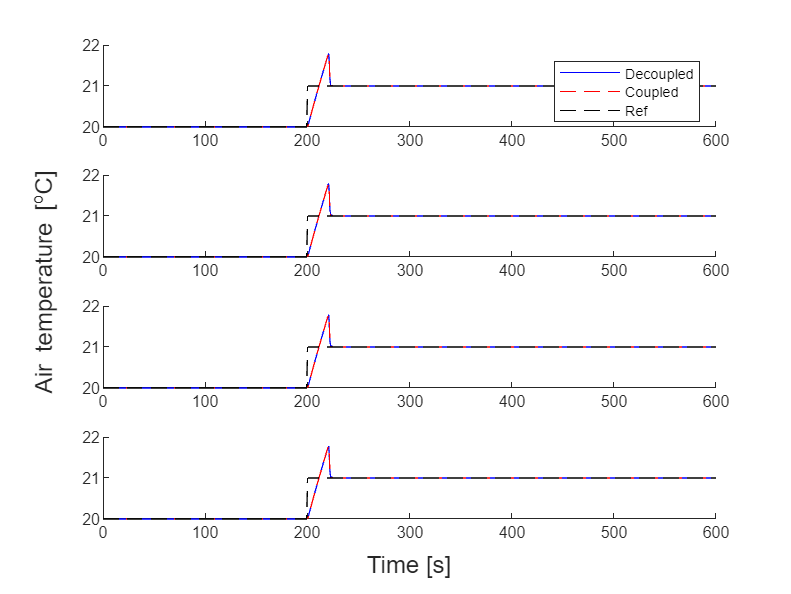


Ks = zeros(1,3,param.n);
for j=1:param.n
    Ks(1,2:3,j) = Ksof(j,2*(j-1)+1:2*j);
end
param.ctrl.Ks = Ks;

[decoupledResults,coupledResults] = util.SimulateStep(param,"Examination_Output_Feedback_alpha",0);


eig(param.model.A + param.model.B *Ksof*Cy)

ans =   -0.9574 + 2.9363i
  -0.9574 - 2.9363i
  -0.9895 + 3.4703i
  -0.9895 - 3.4703i
  -1.0111 + 3.6750i
  -1.0111 - 3.6750i
  -1.0066 + 3.7992i
  -1.0066 - 3.7992i
  -0.6305 + 0.0000i
  -0.5585 + 0.0000i
